# Evaluación de saltos verticales mediante tres tipos de tecnologías.

Se trata de estimar en qué instante y con qué altura se efectuaron tres saltos verticales. Para ello se emplearán los datos registrados por tres sistemas diferentes:

- un sistema de visión artificial con marcadores de la posición

- una plataforma de fuerzas sobre la que se realizó el salto, y los correspondientes 

- unos acelerómetros situados en el centro de gravedad del saltador

Las funciones de la librería que se utilizan son: 

- buscamaximosth

- eventossalto

- doble_cumsum

- doble_cumsum_thong

## Evaluación mediante los datos de la cámara.

En primer lugar se cargan de una archivo los datos obtenidos del procesamiento de la cámara.

filename='../simur_data/SALCAM.trc';
datoscam=load(filename);

Sabemos que los tres saltos se producen entre las muestras 201 y 1400, y que los datos de desplazamiento vertical están registrados en la columna número 4 del archivo. No analizamos el resto de la señal. También sabemos que la frecuencia de muestreo fue de 100Hz

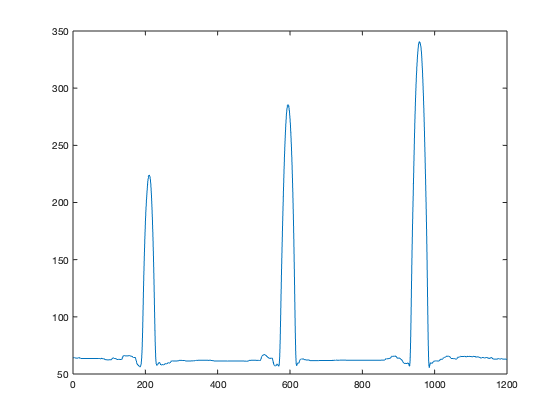

vertcamera=datoscam(201:1400,4);
plot(vertcamera);

Vemos el desplazamiento realizado a lo largo del tiempo, tal y como se registro mediante la cámara.

Para evaluarlo numéricamente: Primero localizamos los 3 máximos de la señal, correspondientes a cada salto.

maximos=buscamaximosth(vertcamera,100);
ind_max=find(maximos==1)

ind_max =    209   594   957


Calculamos la posición inicial antes del salto suponiendo que se corresponde a los datos iniciales.

minimo=mean(vertcamera(1:50))

minimo = 63.7840

Calculamos el momento posterior al salto en el que estamos de nuevo por debajo del valor inicial. (buscamos hasta un máximo de 2s)

ind_fin=[]; 
for i=1:length(ind_max)
    for j=ind_max(i):ind_max(i)+200
        if(vertcamera(j)<minimo)
            ind_fin(i)=j; %#ok<SAGROW> 
            break
        end
    end
end
ind_fin

ind_fin =    229   617   984


Buscamos de la misma manera el inicio del salto hacia valores anteriores al máximo.

ind_inicio=[];
for i=1:length(ind_max)
    for j=ind_max(i):-1:ind_max(i)-200
        if(vertcamera(j)<minimo)
            ind_inicio(i)=j; 
            break
        end
    end
end
ind_inicio

ind_inicio =    189   571   932


Tenemos segmentados los tres saltos del ejemplo

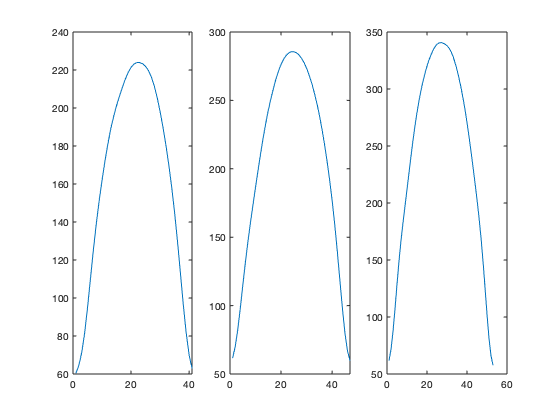

subplot(1,3,1); plot(vertcamera(ind_inicio(1):ind_fin(1)));
subplot(1,3,2); plot(vertcamera(ind_inicio(2):ind_fin(2)));
subplot(1,3,3); plot(vertcamera(ind_inicio(3):ind_fin(3)));

Finalmente procedemos a calcular tanto la altura como la duración registradas por la camara y convertirlas a metros y segundos respectivamente.

for i=1:length(ind_max)
    alturaCam(i)=(vertcamera(ind_max(i))-minimo)/1000; %#ok<SAGROW> 
end
for i=1:length(ind_fin)
    tiemposCam(i)=(ind_fin(i)-ind_inicio(i))/100; %#ok<SAGROW> 
end
alturaCam

alturaCam =     0.1594    0.2218    0.2767



tiemposCam

tiemposCam =     0.4000    0.4600    0.5200


## Evaluación mediante los datos de una plataforma de fuerza

Igual que antes procedemos a cargar los archivos, esta vez registrados en un excel por el software de la plataforma.

filename='../simur_data/SALPF.xls';
datospf=load(filename);

Sabemos que los tres saltos se producen entre las muestras 100 y 1500. No analizamos el resto de la señal. Además los datos de fuerza de cada uno de los pies están en las columnas 2 y 3 del archivo excel. También sabemos que la frecuencia de muestreo fue de 100Hz

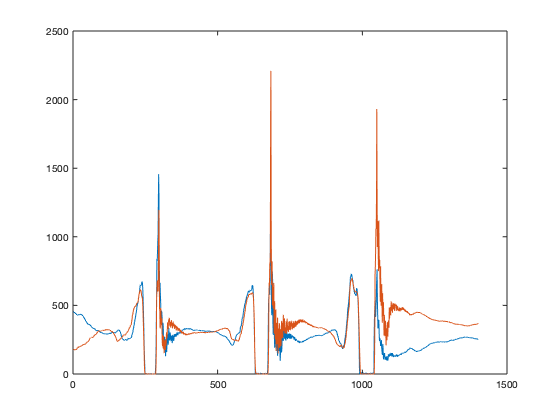

inicio=100;
fin=1500;
figure;plot(datospf(inicio:fin,2:3));

Los saltos se corresponden con el tiempo en el que todo el cuerpo está en el aire, y por lo tanto no se registra ninguna fuerza sobre la plataforma.

Sumamos las dos fuerzas, correspondientes a cada pie, para tener una única fuerza total

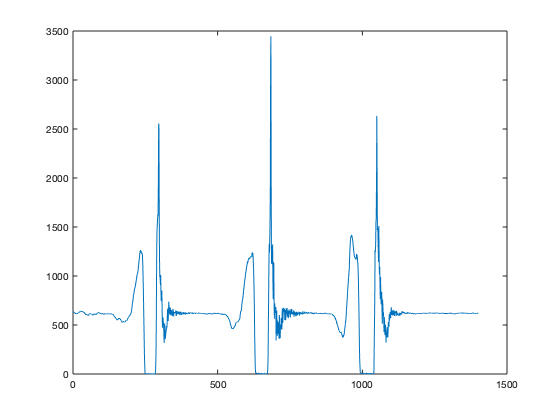

fuerzas=sum(datospf(inicio:fin,2:3),2);
plot(fuerzas);

Segmentamos la señal comparandola con un valor bajo que solo se produce justo al despegar y/o aterrizar.

eventos=diff(fuerzas>70);
ind_ini=find(eventos==-1)

ind_ini =    248
   629
   992


ind_fin=find(eventos==1)

ind_fin =          285
         673
        1040


Las duraciones de cada salto las calculamos directamente como la diferencia de tiempos:

tiemposPF=(ind_fin-ind_ini)/100

tiemposPF =     0.3700
    0.4400
    0.4800


Las alturas alcanzadas las calculamos en función de la ecuación del movimiento en caida libre

alturaPF=9.81*tiemposPF.^2/8

alturaPF =     0.1679
    0.2374
    0.2825


## Evaluación mediante los datos registrados por los acelerómetros Xsens en el COG

Igual que antes procedemos a cargar los archivos, esta vez registrados en un archivo de texto.

filename='../simur_data/SAL.log';
datosxs=load(filename);

Sabemos que los tres saltos se producen entre las muestras 400 y 1600. No analizamos el resto de la señal. Además los datos de aceleraciones están en las columnas 2,3 y 4 de la señal. También sabemos que la frecuencia de muestreo fue de 100Hz

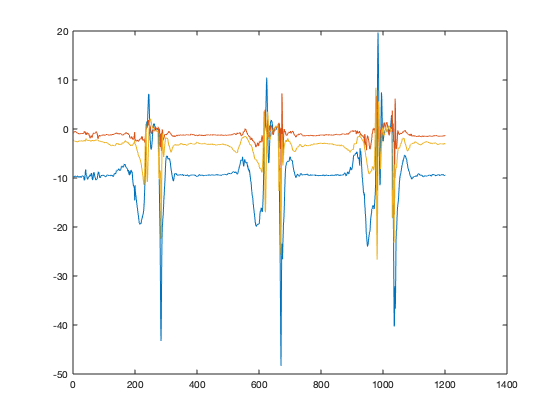

inicio=400;
fin=1600;
acc=datosxs(inicio:fin,2:4);
plot(acc)

Vemos que la segunda y tercera columnas tienen las aceleraciones antero-posteriores y medio-laterales. En la primera columna está la aceleración vertical, pero con el signo invertido. 

Procedemos a usar la función para detectar los eventos de un salto a partir de la aceleración que está incluida en la toolbox. Esta función devolvera en la columna 1, el tiempo, en la 2 el inicio del salto, en la 3 el contacto al final del salto, en la 4 el apoyo con fuerza después del salto y en la 5 el inicio de la preparación para el contacto. 

eventos=eventossalto(-acc(:,1));

Los instantes de inicio del salto son:

inicios=find(eventos(:,2))

inicios =    238
   618
   983


Y los de final del salto son:

finales=find(eventos(:,4))

finales =          283
         670
        1035


Las aceleraciones durante los 3 saltos son:

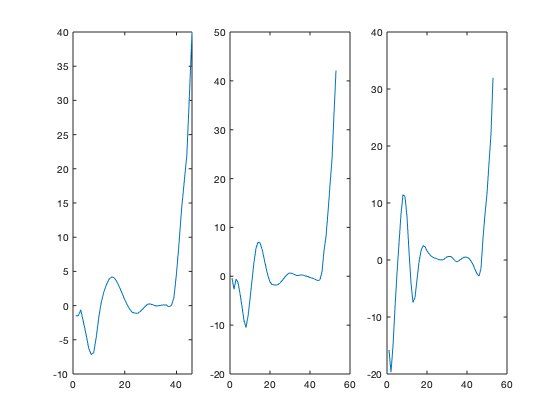

subplot(1,3,1); plot(-acc(inicios(1):finales(1),1));
subplot(1,3,2); plot(-acc(inicios(2):finales(2),1));
subplot(1,3,3); plot(-acc(inicios(3):finales(3),1));

La duración del salto es simplemente la diferencia entre los instantes iniciales y finales.

tiemposxs=(finales-inicios)/100

tiemposxs =     0.4500
    0.5200
    0.5200


Las alturas las calculamos de acuerdo a la duración del salto y la ecuación de caida libre.

alturaxs=9.81*tiemposxs.^2/8

alturaxs =     0.2483
    0.3316
    0.3316


Otra opcion sería calcularlas en función de la doble integral de la aceleración.

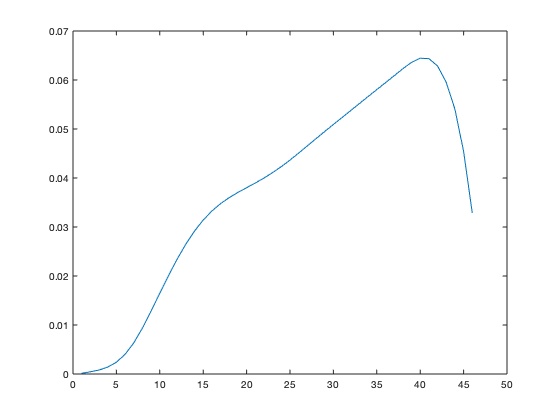

figure;
plot(doble_cumsum(acc(inicios(1):finales(1)),100));

pero como se ve en la gráfica el máximo es del orden de 6cm, muy alejado del real. Esto se debe a que habría que integrar no desde el instante de despegue (que tiene velocidad inicial distinta de cero) sino desde el inicio del movimiento. Pero dado que el centro de gravedad baja para tomar impulso, luego se despega, y al aterrizar vuelve a descender para amortiguar la caida, el proceso se complica mucho y el cálculo basado en el tiempo de duración es mejor. 

En cualquier caso, podríamos intentar una doble integral más sofisticada en la búsqueda de mejores resultados, por ejemplo:

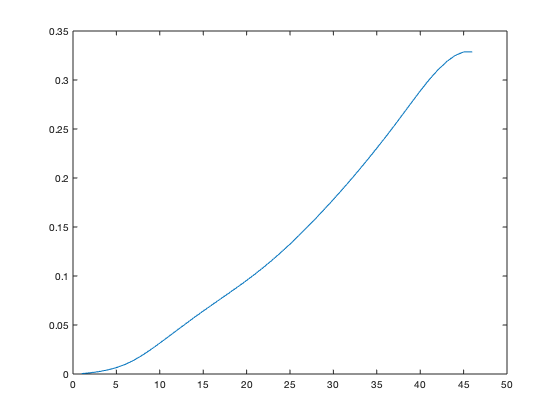

plot(doble_cumsum_thong(acc(inicios(1):finales(1)),100));

Comparando los resultados obtenidos por cada método:

[tiemposPF, tiemposxs , tiemposCam'] 

ans =     0.3700    0.4500    0.4000
    0.4400    0.5200    0.4600
    0.4800    0.5200    0.5200



[alturaPF, alturaxs, alturaCam']

ans =     0.1679    0.2483    0.1594
    0.2374    0.3316    0.2218
    0.2825    0.3316    0.2767


Los resultados obtenidos mediante acelerometría difieren claramente respecto a los otros dos métodos.    